# Proyecto - Wireless 2022

#### Llorente, J. Fermín - P. Agustín Roncagliolo - CoMyS (E1605) 2022

## 1. Introducción

    La función CanalFlat.m provista genera realizaciones de la ganancia de un canal plano, con desvanecimiento Rayleigh, y espectro Doppler de acuerdo al modelo de Clarke. Devuelve en la variable `h` la ganancia compleja del canal con correlación *Jakes* normalizada para que tenga ganancia media unitaria. Esta ganancia es el equivalente a $c(\tau,t)$ para un $t$ dado. 

CanalFlat;

Una vez que se corrió el Script provisto, se puede graficar la magnitud de la ganancia de canal para los distintos retardos, siendo la misma una realización en un $t$ dado.

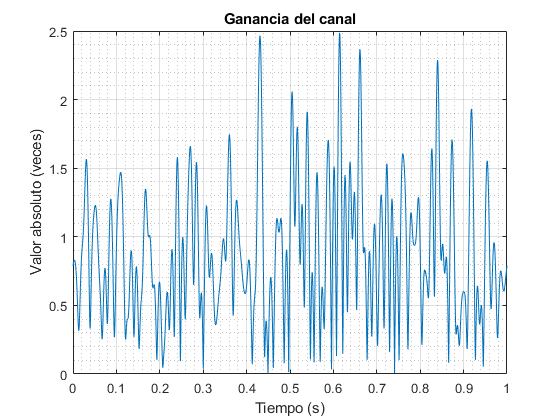

% Gráfica de la ganancia de canal
figure;
plot((0:N-1)*ts, abs(h)), grid on, grid minor;
title('Ganancia del canal'), ylabel('Valor absoluto (veces)'), xlabel('Tiempo (s)');

Además, es posible graficar el espectro *Doppler* de esta realización de canal. 

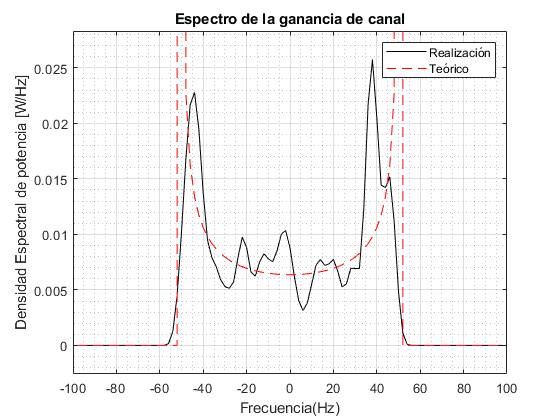

[DOP,ff] = pwelch(h,[],[],2*fr,fs);
S_a_neg = (ff>-fDm & ff<fDm).*1./(pi*fDm*sqrt(1-(ff/fDm).^2));  %Espectro Doppler teórico.
figure;
plot(ff,DOP,'k'), grid on, grid minor, hold on;
title('Espectro de la ganancia de canal'), ylabel('Densidad Espectral de potencia [W/Hz]'), xlabel('Frecuencia(Hz)');
ylim([-0.1*max(DOP) max(DOP)*1.1]);
plot(ff,S_a_neg,'--r');
legend('Realización','Teórico');

Ya sabemos que se define el *Power Delay Profile *o *Multipath Intensity Profile *como 

$A_c(\tau) \triangleq A_c(\tau,0) = \mathbb{E}\left\{ |c(\tau,t)^2| \right\}$.

De manera que si obtenemos $c(\tau,t_0)$ es necesario generar muchas realizaciones para poder calcular su esperanza y de esa manera obtener el *Power Delay Profile*. 

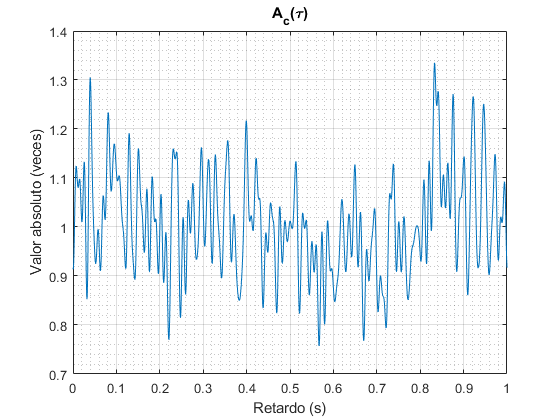

L = 100; %Realizaciones.
C = zeros(length(h),L);
C(:,1) = h;
for i=2:L
    CanalFlat;
    C(:,i) = h;
end
A_c = mean(abs(C).^2,2);
figure;
plot((0:N-1)*ts, A_c), grid on, grid minor;
title('A_c(\tau)'), ylabel('Valor absoluto (veces)'), xlabel('Retardo (s)')